## Initialize

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## Load Training Data

downloadFolder = fullfile('AirCompressorDataset');
ads = audioDatastore(downloadFolder,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル
uniqueLabels = unique(ads.Labels);

## Visualize data

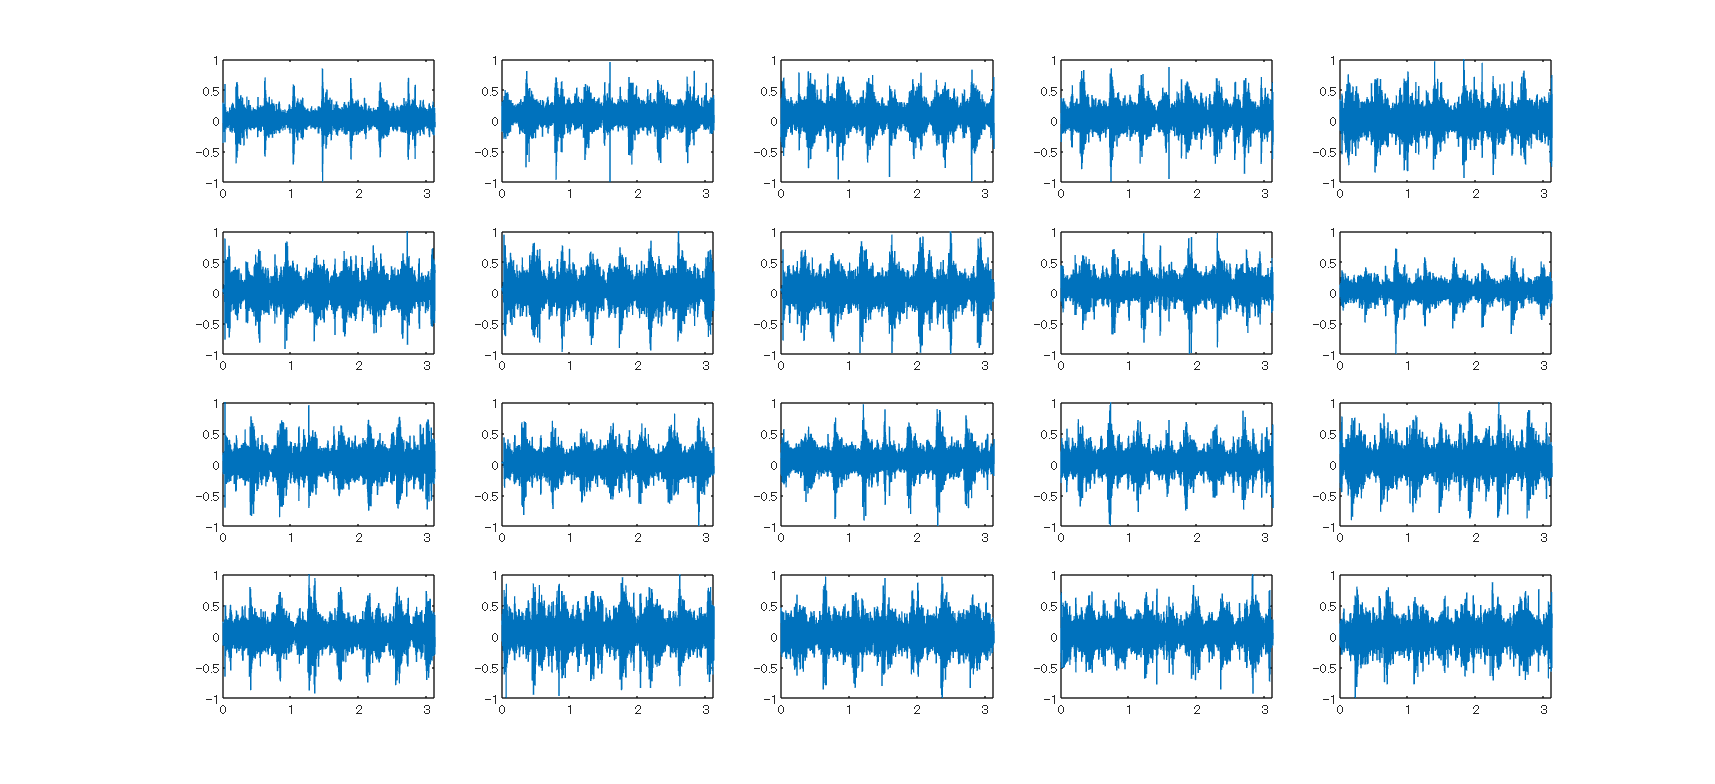

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
label=1;
dispnum=20;
idx = find(ads.Labels==uniqueLabels(label),dispnum);

for n = 1:dispnum
    
    [x,fs] = audioread(ads.Files{idx(n)});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(4,dispnum/4,n);
    plot(t,x);
    %title(string(uniqueLabels(label)));
end